# Eksamenssæt Forår 2024

## Spørgsmål 1 - Sandsynlighedsteori

En virksomhed, der sælger to produkter A og B, vil gerne målrette deres markedsføring og laver derfor en undersøgelse af hvilke produkter, deres kunder køber. 

Undersøgelsen viser, at: 

70% køber produkt A 

45% køber produkt B 

80% af kunderne, der køber produkt B, køber også produkt A 

Vi får her 3 sandsynligheder


$$\Pr \left(A\right)=70%$$



$$\Pr \left(B\right)=45%$$



$$\Pr \left(A|B\right)=80%$$


buyA = 0.70;
buyB = 0.45;
buyAWhenB = 0.80;

a) Hvor mange (%) kunder køber både produkt A og B? 

Her skal vi finde $\Pr \left(A\cap B\right)$

Med bayes regel gælder følgende: $\Pr \left(A\cap B\right)=\Pr \left(A|B\right)*\Pr \left(B\right)$

buyAandB = buyAWhenB * buyB

buyAandB = 0.3600

b) Hvor mange (%) kunder, som køber produkt A, køber også produkt B? 

Her skal vi finde $\Pr \left(B|A\right)$

Her kan vi også bruge Bayes regel:


$$\Pr \left(B|A\right)=\frac{\Pr \left(A|B\right)*\Pr \left(B\right)}{\Pr \left(A\right)}$$


buyBWhenA = (buyAWhenB * buyB) / buyA

buyBWhenA = 0.5143

c) Hvor mange (%) kunder, køber kun ét produkt? 

Vi skal finde følgende: $\Pr \left(A\cup B\right)-\Pr \left(A\cap B\right)$

Vi ved også følgende: $\Pr \left(A\cup B\right)=\Pr \left(A\right)+\Pr \left(B\right)-\Pr \left(A\cap B\right)$

buyOnlyOne = buyA + buyB - buyAandB * 2

buyOnlyOne = 0.4300

## Spørgsmål 2 - Stokastiske variable

En stokastisk variabel, X, er givet ved tæthedsfunktionen (pdf):

syms K x
pdf = piecewise((1<=x) & (x<3), K*x, (3<= x) & (x < 4), K , 0)

$$pdf = \left\{ \begin{array}{cl} K\,x & \text{ if }x\in \left[1,3\right)\\ K & \text{ if }x\in \left[3,4\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

a) Find K, med visning af mellemregning, og skitsér tæthedsfunktionen fx(x). 

Vi ved at integralet af pdf'en (tæthedsfunktionen) skal give 1.

Så vi kan finde K ved at sætte ligningen lig 1 og så løse for K.

Alternativt kan man sætte K lig med 1 og integrere mellem 1 og 4 (grænseværdierne) og K ville så skulle blive 1 over resultatet (I følgende tilfælde vil resultatet blive 5 og K skal dermed blive 1/5)

newK = solve(int(pdf, 1, 4) == 1, K)

$$newK = \frac{1}{5}$$

pdf = subs(pdf,K, newK)

$$pdf = \left\{ \begin{array}{cl} \frac{x}{5} & \text{ if }x\in \left[1,3\right)\\ \frac{1}{5} & \text{ if }x\in \left[3,4\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

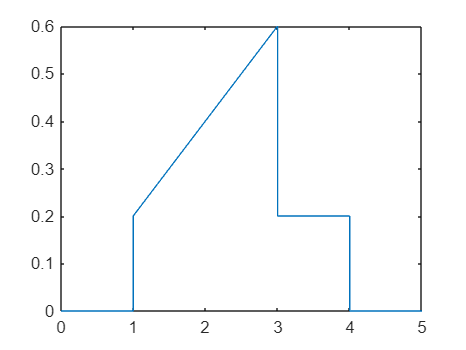

fplot(pdf, [0 5])

b) Find middelværdi og varians af X, med visning af mellemregninger. 

Vi ved at for at få middelværdien kan man bruge følgende formel


$$E\left\lbrack X\right\rbrack =\int_{-\infty }^{\infty } x*f_x \left(x\right)\mathrm{dx}$$


og vi ved også at man kan finde variansen med følgende formel:


$${\mathrm{Var}\left\lbrack X\right\rbrack =\sigma_x }^2 =\int_{-\infty }^{\infty } {\left(x-\overline{x} \right)}^2 *f_x \left(x\right)\mathrm{dx}$$


syms x
meanX = int(@(x)x*pdf, x, -inf, inf)

$$meanX = \frac{73}{30}$$

varX = int(@(x)(x-meanX)^2*pdf, x, -inf, inf)

$$varX = \frac{491}{900}$$

c) Find og skitser, med visning af mellemregninger, cdf’en af X, Fx(x)

Vi ved at ved at integrere pdf'en mellem -uendelig og x kan man få cdf'en

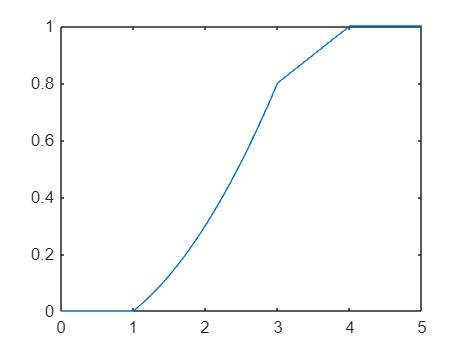

cdf = int(pdf, -inf, x);
fplot(cdf, [0 5])

## Spørgsmål 3 - Stokastiske processer

En tids-diskret stokastisk process X[n] er givet ved:


$$X\left\lbrack n\right\rbrack =Y\left\lbrack n\right\rbrack +2*Y\left\lbrack n+1\right\rbrack$$


Hvor Y[n] er i.i.d. og Y[n] ~ Uniform[-1, 1]. Uniform[] angiver den diskrete uniforme fordeling.

a) Tegn 11 samples (n = 0,...,10) af 3 realisationer af X[n] og vis desuden hvordan realisationerne er fremkommet med brug af random number generator.

b)Find, med visning af mellemregninger, ensemble middelværdi og ensemble varians af X[n].

c) Er X[n] WSS og er den ergodisk, begrund dit svar?

d) Find, med visning af mellemregninger, Rxx[tau] for tau = 0, tau = 1 og tau = 2.

%a.
n=0:10;

realisations=3;

Y=zeros(realisations,length(n));
X=zeros(realisations,length(n));
for j=1:realisations
    for i=1:length(n)
        Y(j,i)=randi([-1 1],1,1);
    end
    
    for i=1:length(n)-1
        X(j,i)=Y(j,i)+2*Y(j,i+1);
    end
    X(j,length(n))=Y(j,length(n));
end

figure(1)
plot(n,X(1,:))

figure(2)
plot(n,X(2,:))

figure(3)
plot(n,X(3,:))


%b.

%E[X[n]]=E[Y[n]+2*Y[n+1]]=E[Y[n]]+E[2*Y[n+1]]
%E[X[n]]=E[Y[n]]+2*E[Y[n+1]]
%Eftersom Y er diskret uniformt fordelt fra -1 til 1,
%vil gennemsnittet kunne findes ved at bruge formlen:
%EX=(a+b)/2
%Dermed er gennemsnittet: (-1+1)/2=0
%Dette gennemsnit gælder for alle Y-samples, da der er
%i.i.d.
EX=0

%X[n]=Y[n]+2*Y[n+1]
%Var(X[n])=Var(Y[n]+2*Y[n+1])
%Var(X[n])=Var(Y[n])+2^2*Var(Y[n+1])
%Eftersom variansen for Y[n] og Y[n+1] er den samme:
%Var(X[n])=Var(Y[n])+4*Var(Y[n])=5*Var(Y[n])
%Var(Y[n])=((b-a+1)^2-1)/12=((1-(-1)+1)^2-1)/12
vary = ((((1-(-1)+1)^2)-1)/12);
VarX=vary+4*vary %Var(X[n])


%c.

%Hverken ensemble mean eller varians er tidsafhængig,
%eftersom de ikke afhænger af n, men er konstante værdier.
%Derfor er X[n] WSS.
%Eftersom der ikke er nogen værdi der holdes konstant
%per realisation, og middelværdien og variansen dermed 
%ville kunne findes vha. en enkel realisation, 
%hvis man måler længe nok, er X[n] ergodisk.


%d.

%R_xx(0)=E[X[n]*X[n]]=E[X[n]^2]=VarX+E[X[n]]^2
Rxx0=VarX+EX^2

EYnYn1=0;
EYnYn2=0;
EYn1Yn2=0;

Rxx1=EYnYn1+2*EYnYn2+2*2/3+4*EYn1Yn2


%Rxx2 = E[X[n]X[n+2]] = E[(Y[n]+2*Y[n+1])*(Y[n+2]+2*Y[n+3])]

Rxx2=0

## Spørgsmål 4 - Statistik

Når en metaloverflade udsættes for bestråling med lys, kan der løsrives elektroner fra overfladen. Dette kaldes den fotoelektriske effekt og er fysikken bag f.eks. fotoceller, solceller o.l. 

Teorien siger, at der er en lineær sammenhæng mellem lysets frekvens f og energien K_e af den løsrevne elektron: 

K_e = beta * f - a

hvor 𝛼𝛼 er elektronens løsrivelsesenergi. Hvis lysets frekvens er mindre end cut-off frekvensen 𝑓𝑓𝑐𝑐 = 𝛼𝛼 𝛽𝛽, vil der ikke blive løsrevet elektroner 

For at teste teorien belyses en metaloverflade af et bestemt materiale med lys med forskellige frekvenser, og energien af de løsrevne elektroner måles. Resultaterne af målingerne er:

frekvenser = [4.53 5.12 5.43 6.09 6.35 7.29 7.88 8.65];
energier = [0.18 0.33 0.55 0.71 0.98 1.38 1.46 1.80];

De anvendte formler skal angives i besvarelsen. Der kan ved løsning af opgaven regnes uden de fysiske enheder. 

a) Lav et plot af målepunkterne (energi som funktion af frekvens). 

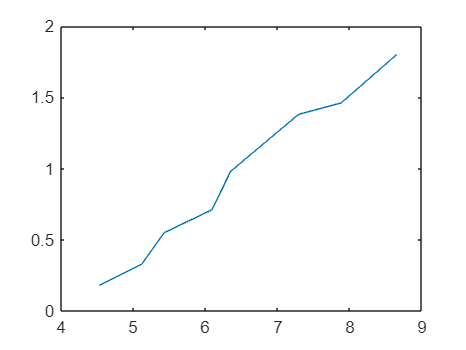

figure();
plot(frekvenser, energier);

b) Bestem v.hj.a lineær regression koefficienterne 𝛼𝛼 og 𝛽𝛽 for den bedste rette linje gennem målepunkterne, og indtegn den rette linje på plottet. 

x = frekvenser;
y = energier;
sxx = sum((x - mean(x)).^2)

sxx = 14.2174

syy = sum((y - mean(y)).^2)

syy = 2.3578

sxy = sum(x.*y- mean(x)*mean(y))

sxy = 5.7481


beta = sxy/sxx

beta = 0.4043


alfa = -(mean(y)-(beta*mean(x)))

alfa = 1.6708


beta*x - alfa

ans =     0.1606    0.3992    0.5245    0.7913    0.8965    1.2765    1.5150    1.8263


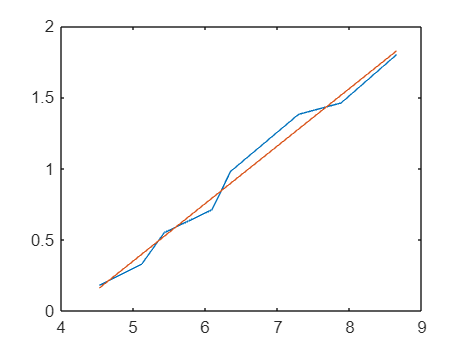


figure();
plot(frekvenser, energier);
hold on;
plot(x, beta*x - alfa)
hold off;

c) Beregn residualerne og lav et residualplot for målepunkterne ift. den lineære regression. Hvad er konklusionen fra residualplottet? 

residuals = y-(beta*x - alfa)

residuals =     0.0194   -0.0692    0.0255   -0.0813    0.0835    0.1035   -0.0550   -0.0263


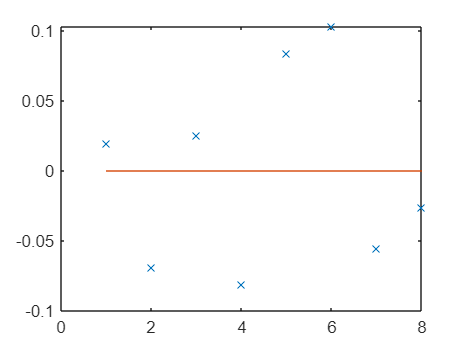

plot(residuals, 'x');
hold on;
plot(1:length(residuals), zeros(length(residuals)));
hold off;

d) Den forventede løsrivelsesenergi for materialet er 𝛼𝛼0 = 1.50 [𝑒𝑒𝑒𝑒]. Opstil en hypotese og en alternativ hypotese for en test af om den målte løsrivelsesenergi stemmer overens med den forventede værdi. 

h0 = 1.50

h0 = 1.5000

e) Beregn p-værdien for testen af løsrivelsesenergien. Begrund den anvendte teststatistik til beregningen. 

Da vi ikke for en givet varians for dataen bruger vi t-statistik til at finde vores p-værdi

s = sqrt(sum((y-mean(y)).^2)/(length(y)-1))

s = 0.5804

t = (mean(y)-h0)/(s/sqrt(length(y)))

t = -2.8084

p = 2 * (1-tcdf(abs(t), length(y)-1))

p = 0.0262

f) Bestem Coefficient of Determination R2 for den lineære regression. Hvad kan konkluderes fra den fundne værdi for R2 ?

r2 = (sxy/sqrt(sxx*syy))^2

r2 = 0.9856

Udfra vores R^2 værdi kan vi se at der er høj sammenhæng og et godt lineært forhold mellem vores data punkter.